# Import a TensorFlow™ Network into MATLAB and Simulink

In this example, you will import a neural network created and trained in TensorFlow™ into MATLAB and Simulink instead of creating and training a network from scratch.

## Unzip the TensorFlow™ Model

The TensorFlow model is available in a zipped folder. Unzip the folder to access it in MATLAB. 

clear
proj = currentProject;
unzip(helper.getPyModelFolder,helper.getCurrPartFolder("P2"))

## Import Network using Deep Network Designer

Launch the Deep Network Designer:

deepNetworkDesigner

Click on "Import" in the "From TensorFlow" option from the Start Page. If you've not installed **Deep Learning Toolbox Converter for TensorFlow Models**, you can first click the "Install" button and then click on "Import" after the installation is complete.

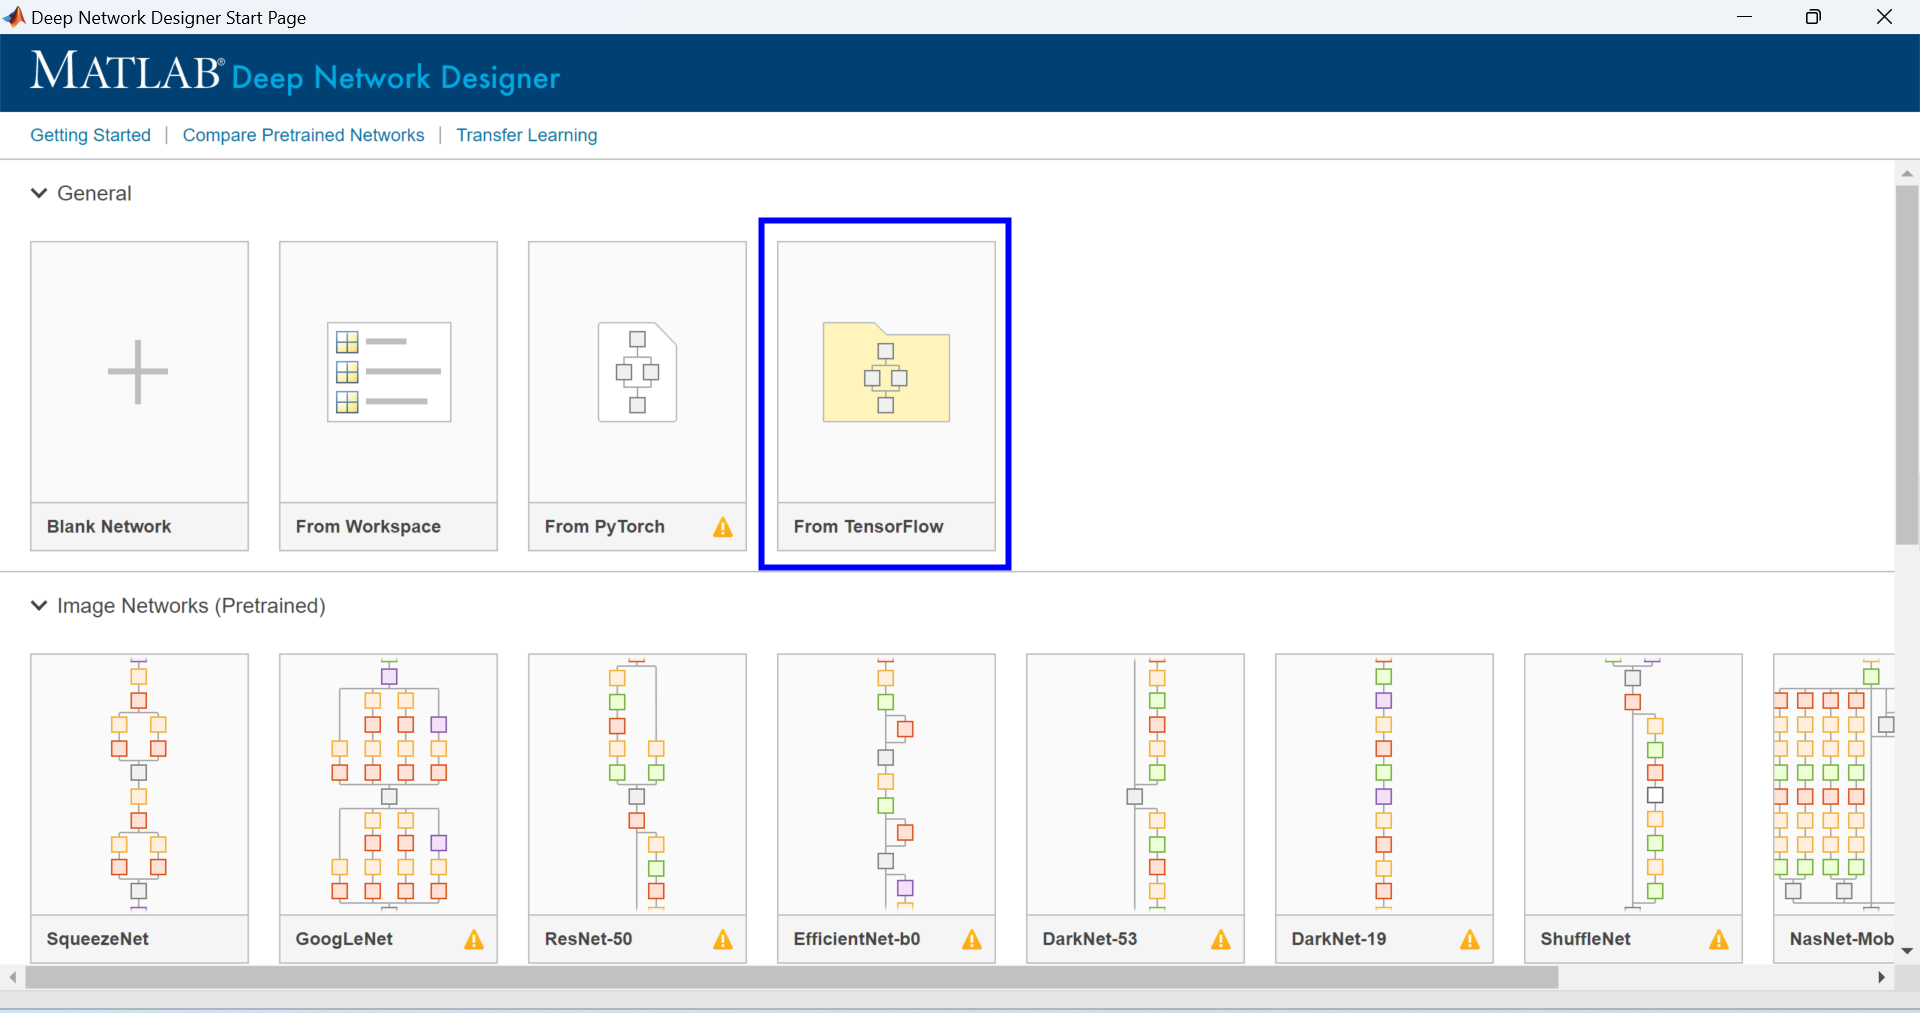

Select the **folder** that contains the TensorFlow model. Click "Import".

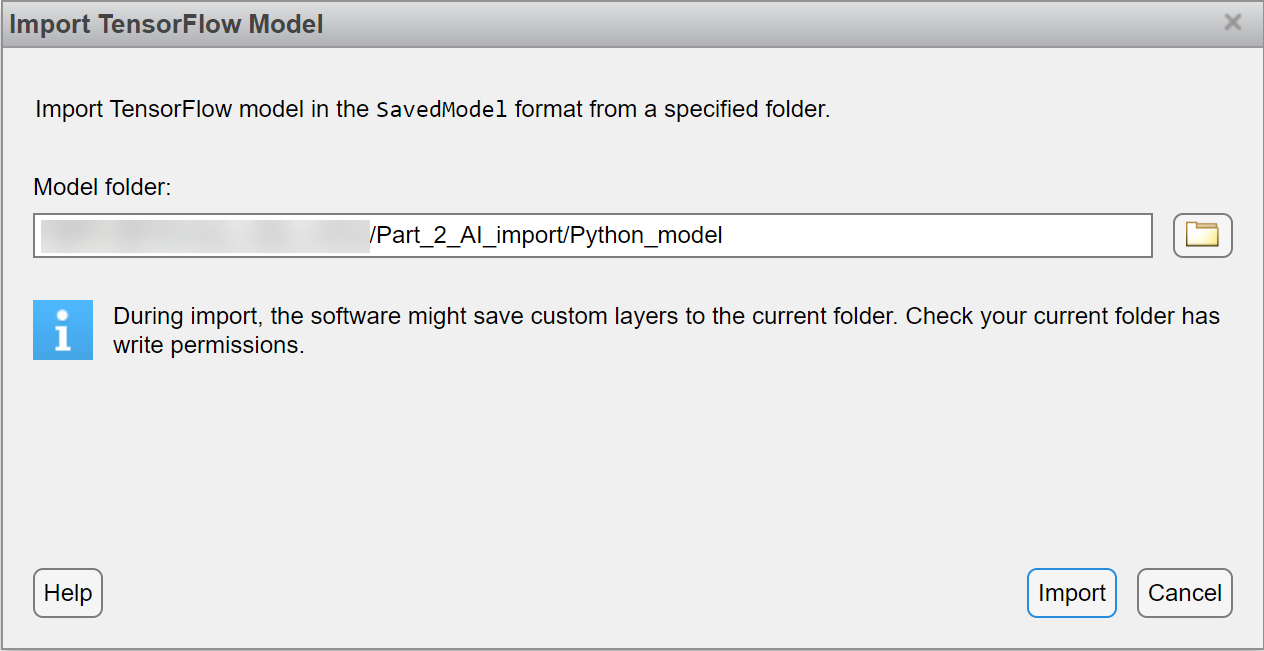

Import Progress is showned in the menu.

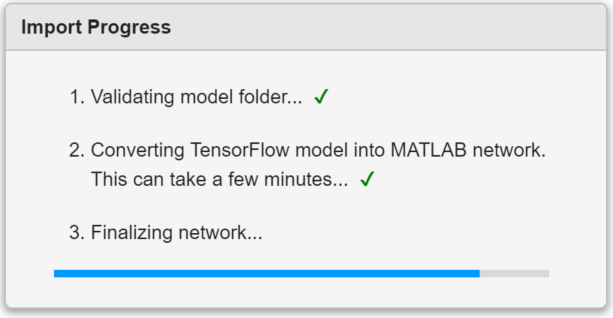

## Review Network Design

After import is complete, click on the "Designer" tab to inspect the network architecture and confirm properties of individual layers.

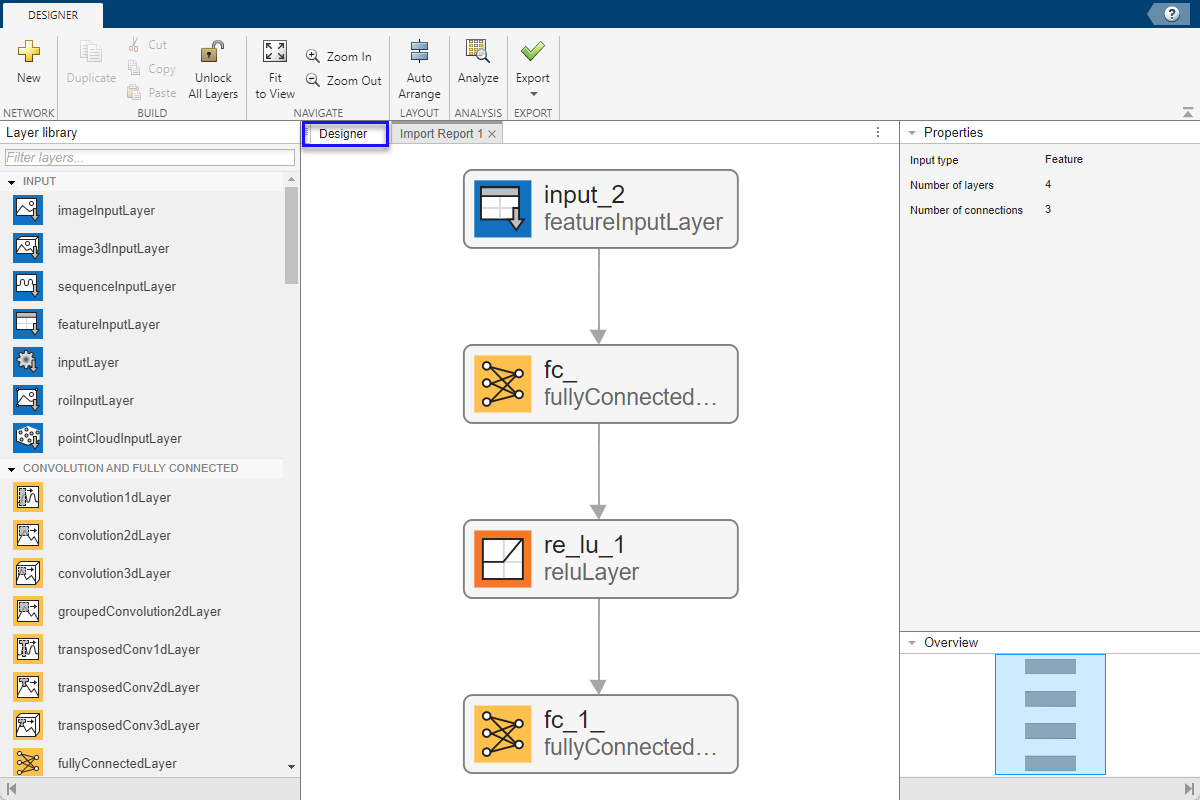

## Export AI Model

Export the AI model to Simulink from the toolstrip.

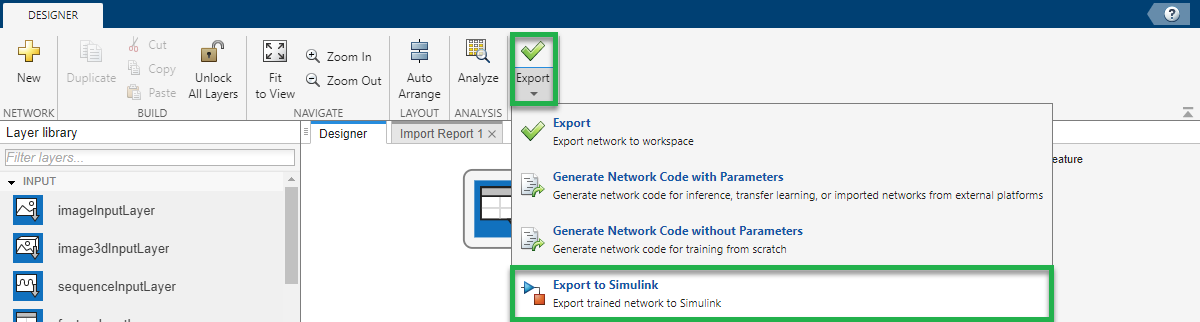

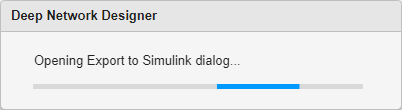

Find a convenient location to save your TensorFlow model and click Export.

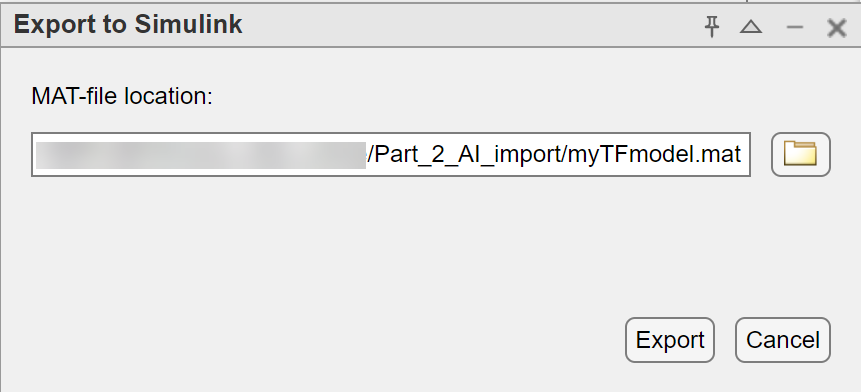

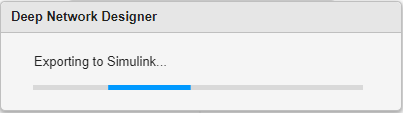

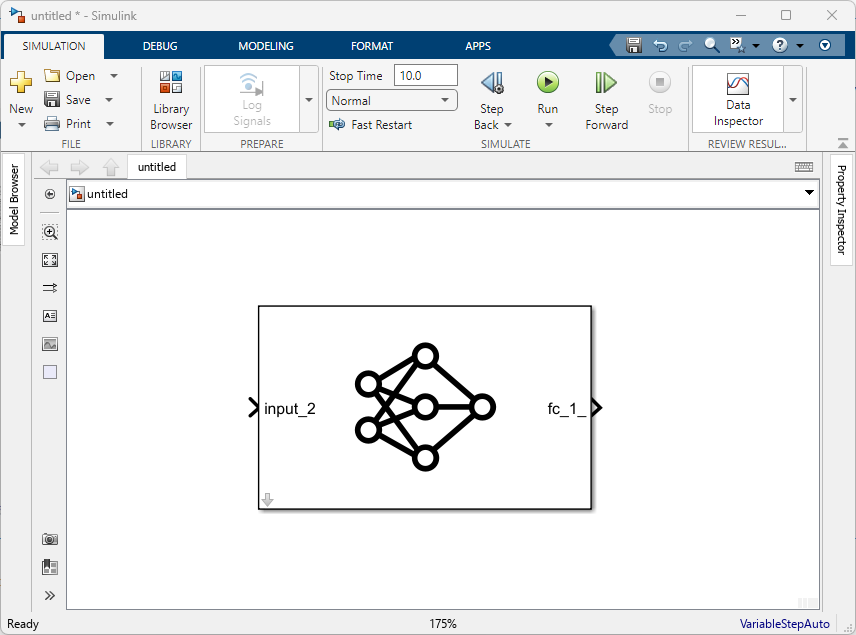

## Specify the input format in the Predict block

Double click on the **Predict Block** to open the **Block Parameters** menu. Specify the **Input data format** as "CB" - this means the input data is formatted as *c*-by-*n* array, where *c* is the number of features, and *n* is the number of observations. 

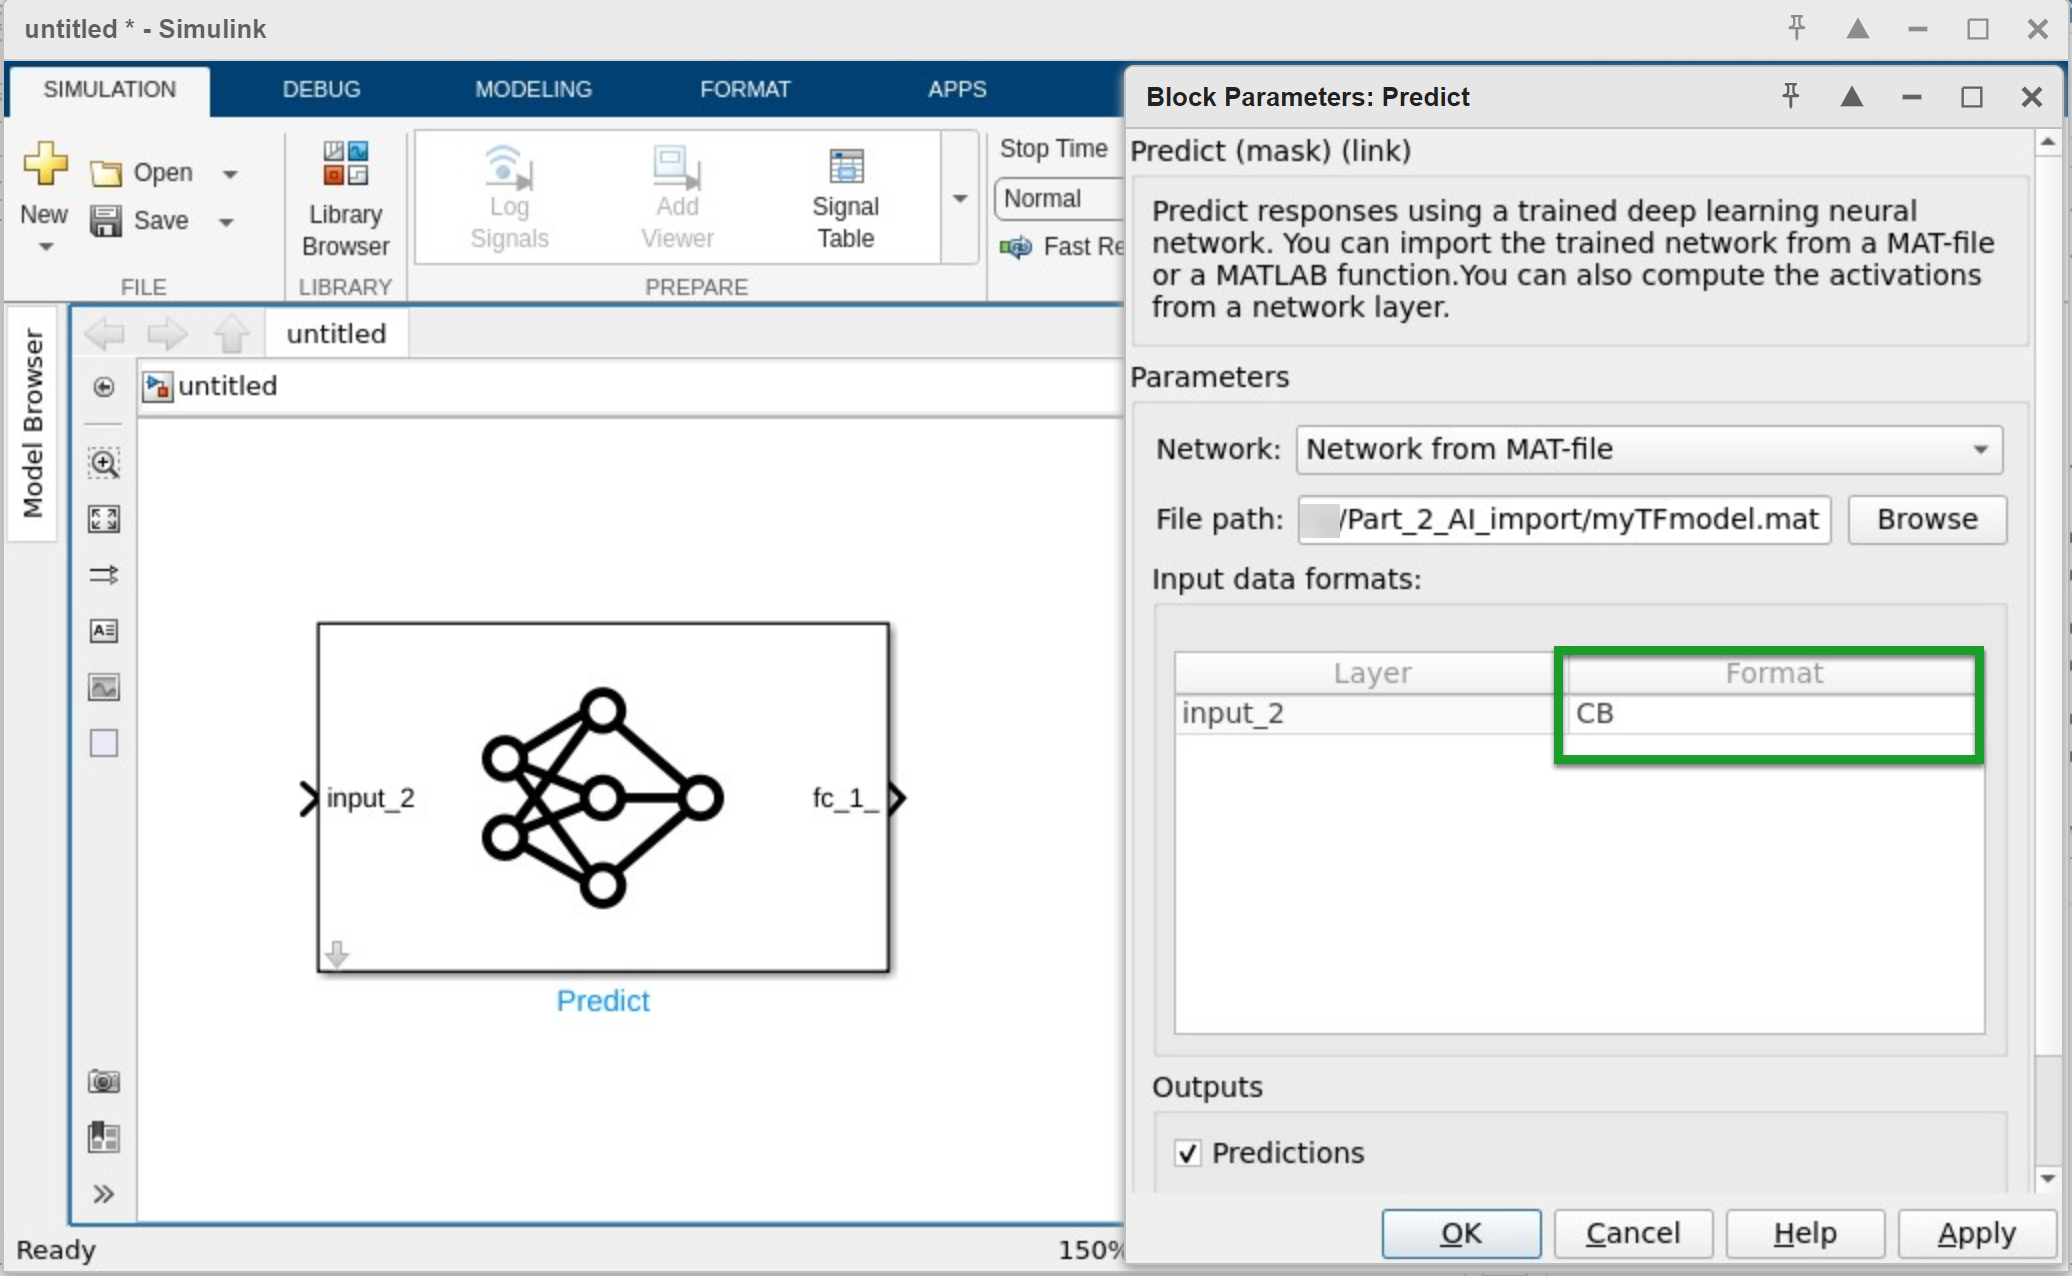

## Configure Model Parameters for Simulations

Open the **Configuration Parameters** dialog (or Ctrl+E) and set **Stop time **to the workspace variable named "step" (which is the total number of simulation steps; this variable will be generated in a later section), and set the solver to "Fixed-step" and "Discrete" with a fundamental step size of 1:

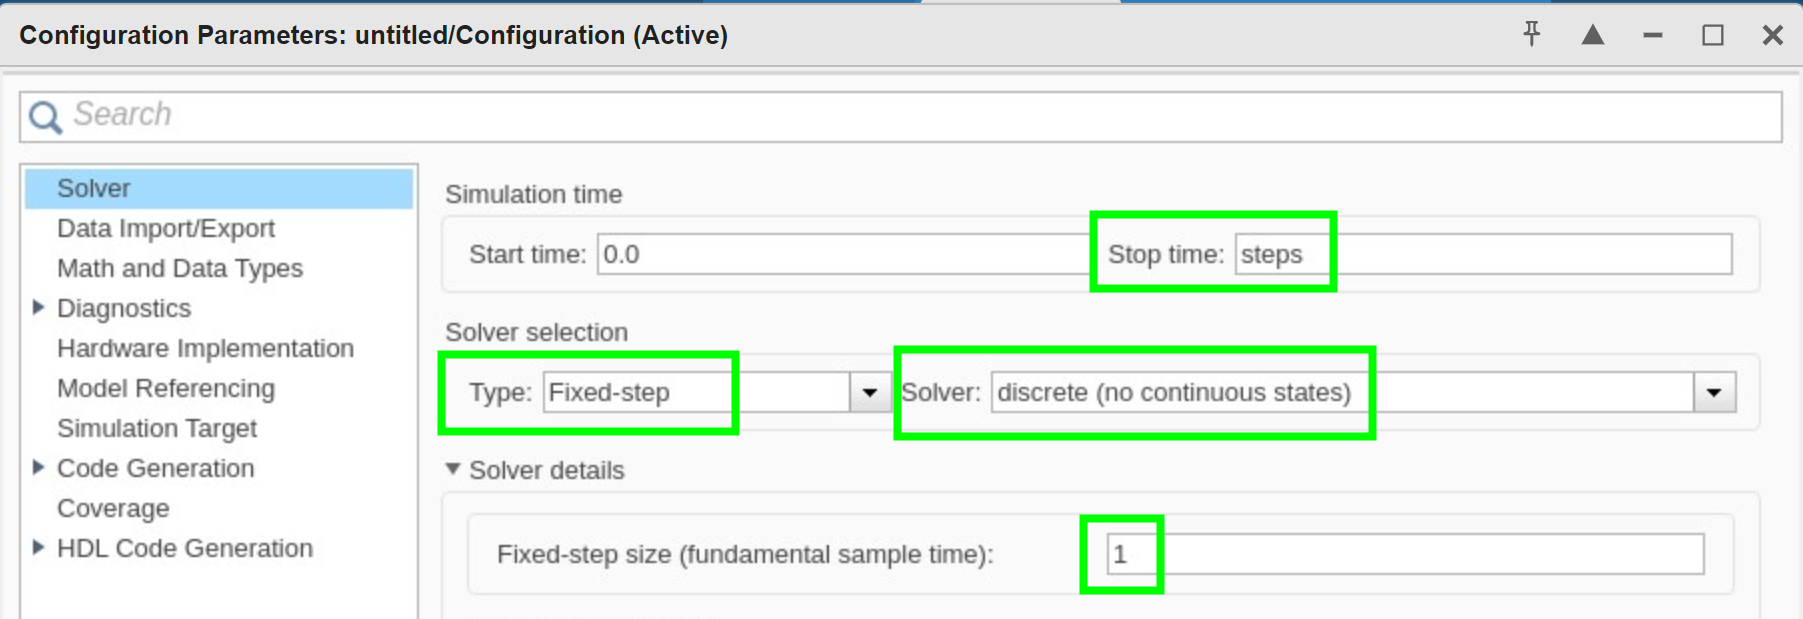

Also, set the **Simulation Target** language to C++:

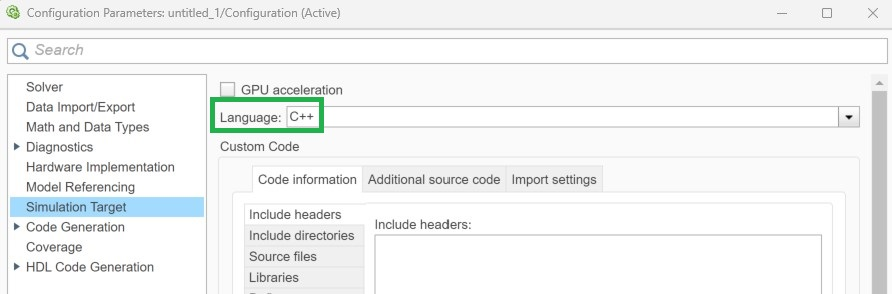

## **Generate the Inputs for Simulink**

In Simulink, there are several ways how you can import data: "From Workspace" block, "Inport" block, "From File" block and others. We are going to use "From Workspace" blocks. We need to generate the inputs for Simulink in the correct format and we can use the left-out test data set.

dataFolder = helper.getDataFolder();
testFile = fullfile(dataFolder,"Test","01_TEST_LGHG2@n10degC_Norm_(05_Inputs).mat");
S = load(testFile);
steps = size(S.X,2);
t = (0:(steps-1))';
X_in = timeseries(single(S.X'), t);
true_SOC = timeseries(single(S.Y'), t);

## **Connect the Model**

Save the model as myE`xampleModel_TF.slx`. Add two "From Workspace" blocks with "X_in" and "true_SOC" for the data variables, respectively. Connect the "X_in" input to the "Predict" block. Connect the "true_SOC" input to a "Scope" block in the following way:

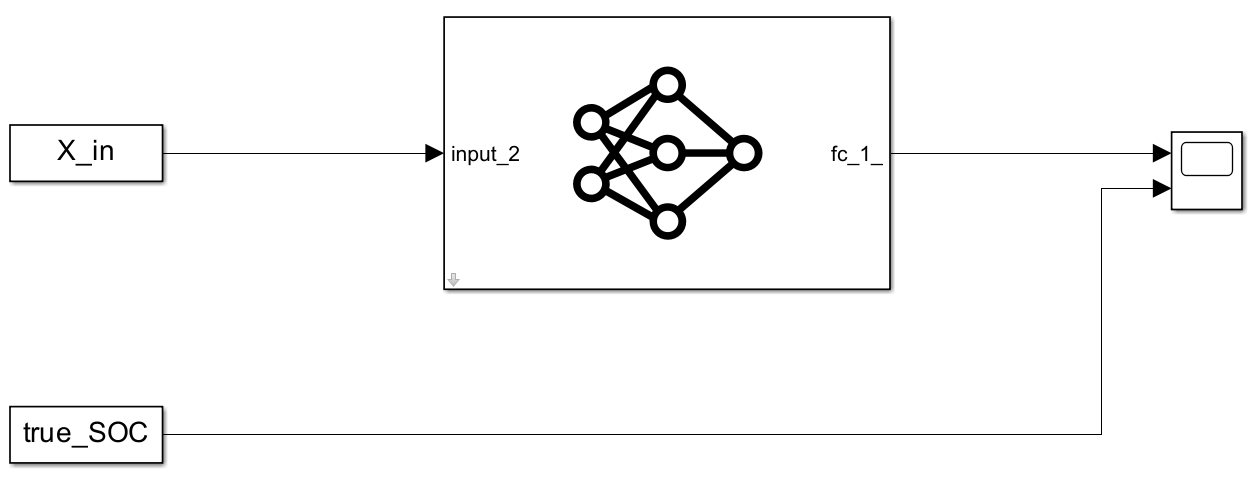

## Run the Simulink Model

Now we can simulate the model by clicking the "Run" button and double-click on the "Scope" block to inspect simulation results:

(You may check `exampleModel_TF_import.slx` if you run into any issues)

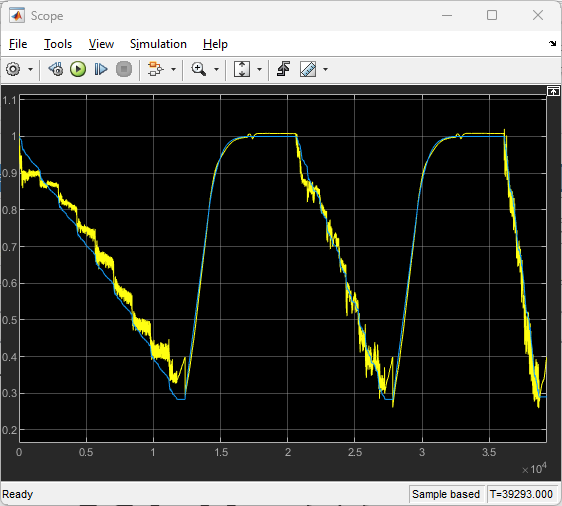

## Alternative: Programmatically Import the Model

Alternatively, you can directly call the **importNetworkFromTensorFlow** function for model import. The imported network is a workspace variable that you can save into a ".mat" file. Then, you can use add a **Predict **block to a new model as it was done in [Exercise_1.mlx](matlab:open('Exercise_1.mlx')).

netDL = importNetworkFromTensorFlow(fullfile(helper.getCurrPartFolder("P2"), "Python_model"));

*Copyright 2024 The MathWorks, Inc.*